s^2

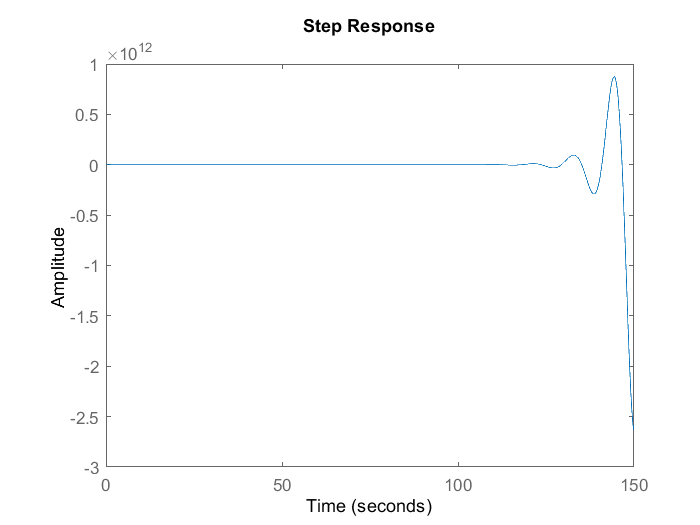

s=tf('s');
k=1;
G=k/(s^2*(s+1)*(s+2));
step(feedback(G,1))


syms s;
G=k/(s^2*(s+1)*(s+2));
y=ilaplace(1/s*G)

$$y = \frac{{\mathrm{e}}^{-2\,t}}{8}-{\mathrm{e}}^{-t}-\frac{3\,t}{4}+\frac{t^{2}}{4}+\frac{7}{8}$$

Opóźnienie e^(-st0)

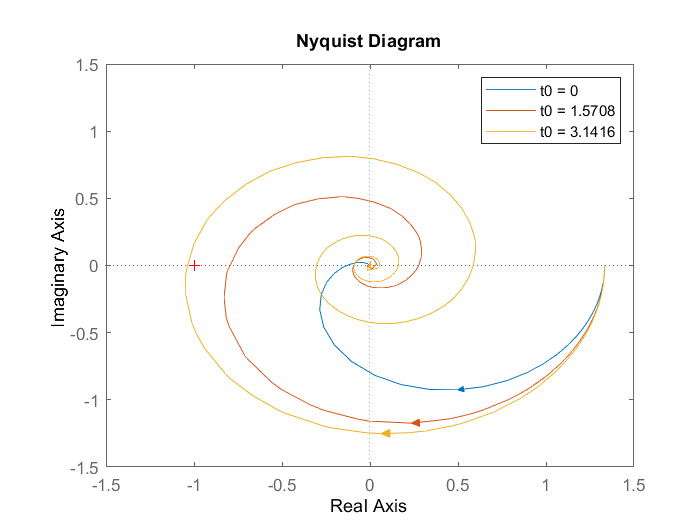

s=tf('s');
legend_names=string([]);
k=8;
for i=1:3
t0=(i-1)*pi/2;
G0=k/((s+1)*(s+2)*(s+3))*exp(-s*t0);
%figure
P=nyquistplot(G0);
setoptions(P,'ShowFullContour','off')
hold on;
legend_names(end+1) = "t0 = "+ t0;
end
hold off;
%disp(legend_names)
legend(legend_names);

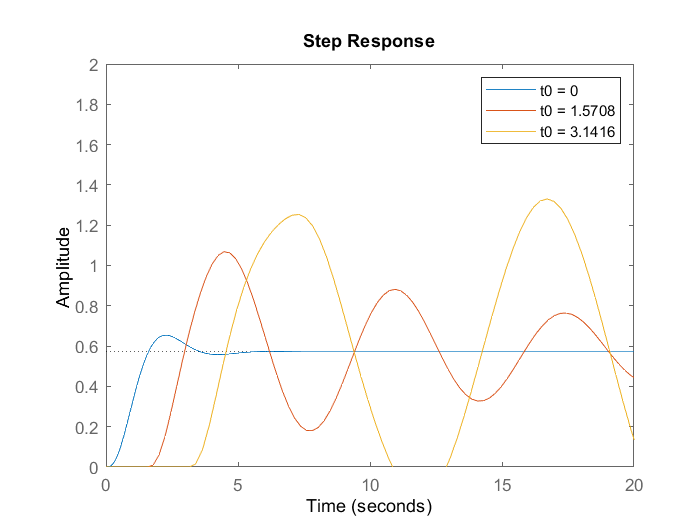


for i=1:3
t0=(i-1)*pi/2;
G0=k/((s+1)*(s+2)*(s+3))*exp(-s*t0);
step(feedback(G0,1));
hold on;
end
hold off;
%disp(legend_names)
xlim([0,20])
ylim([0, 2])
legend(legend_names);

10

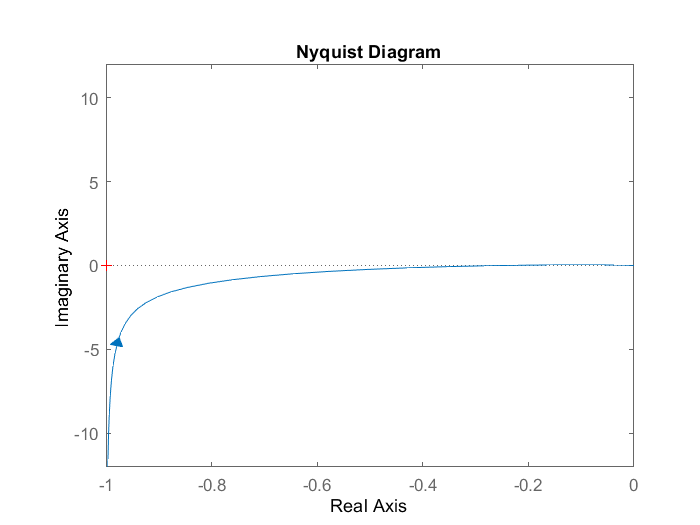

s=tf('s');
k=1;
G0=k/10/s/(5*s+1)^2;
P=nyquistplot(G0);
setoptions(P,'ShowFullContour','off')

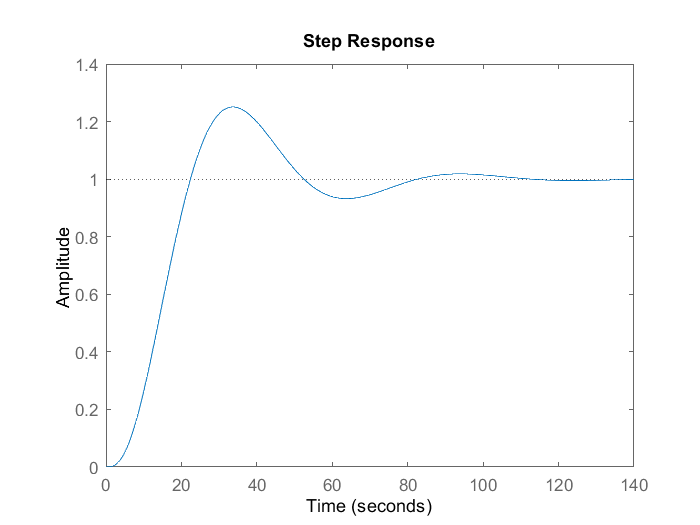

step(feedback(G0,1))

11

s=tf('s');
k=1000;
G0=k/(s+1)^2

G0 =
 
      1000
  -------------
  s^2 + 2 s + 1
 
Continuous-time transfer function.



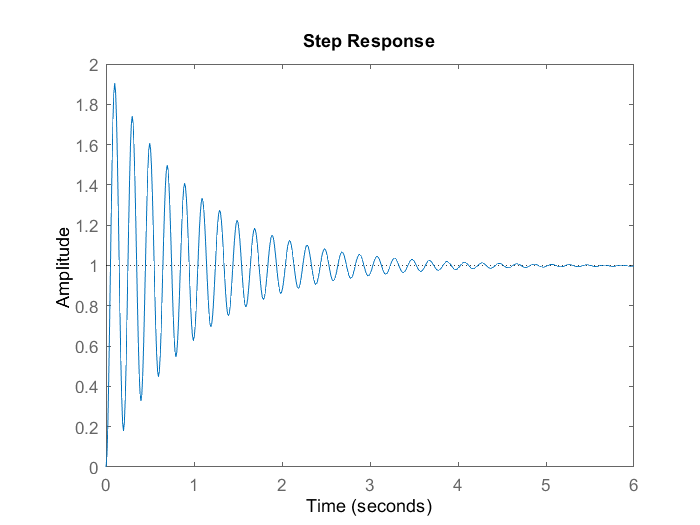

step(feedback(G0,1))

16

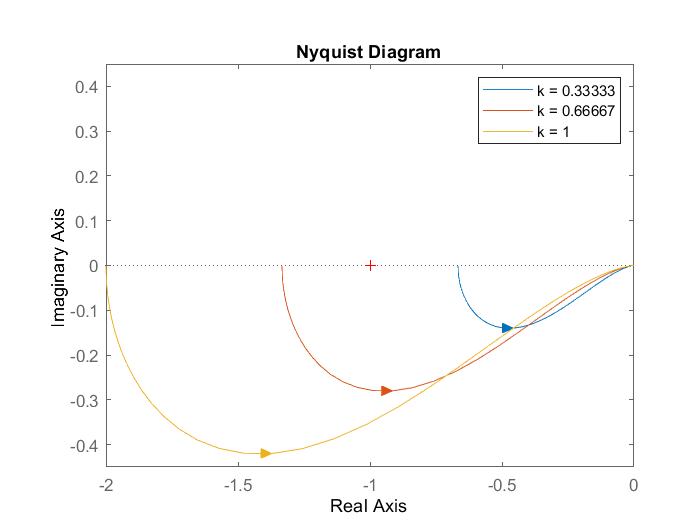

s=tf('s');
legend_names=string([]);
for i=1:3
k=1/3*i;
G0=k/(s+1)/(s-0.5);
%figure
P=nyquistplot(G0);
setoptions(P,'ShowFullContour','off')
hold on;
legend_names(end+1) = "k = "+k;
end
hold off;
%disp(legend_names)
legend(legend_names);

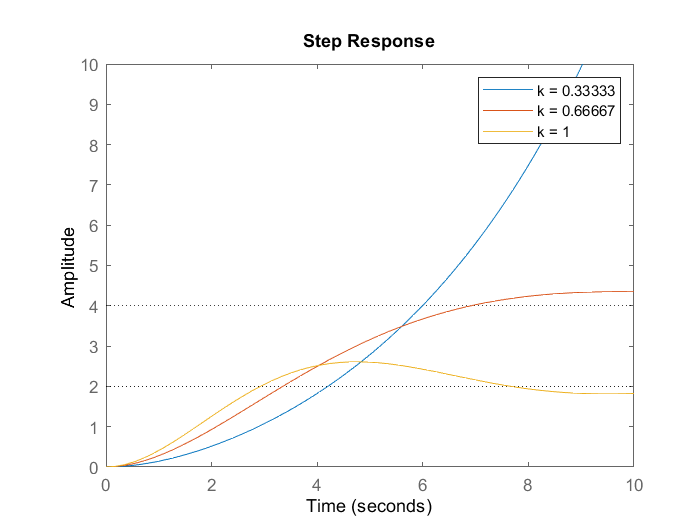


for i=1:3
k=1/3*i;
G0=k/(s+1)/(s-0.5);
step(feedback(G0,1));
hold on;
legend_names(end+1) = "k = "+k;
end
hold off;
%disp(legend_names)
xlim([0,10])
ylim([0, 10])
legend(legend_names);

19/20

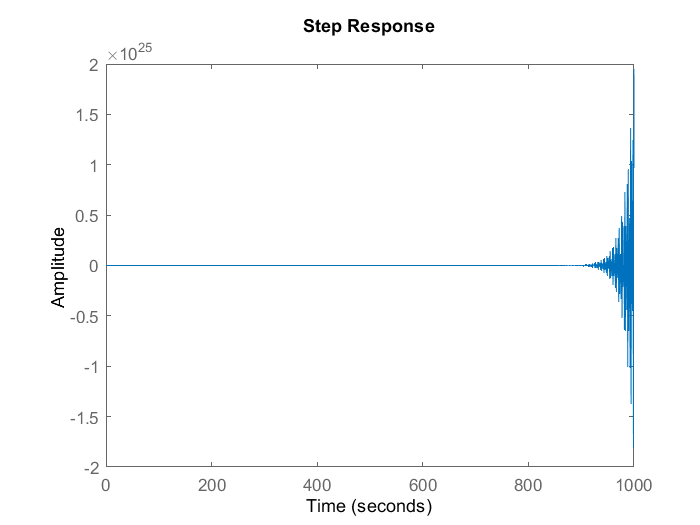

s=tf('s');
G0=10/(s+1)/(0.5*s+1)^2;
step(feedback(G0,1));

21

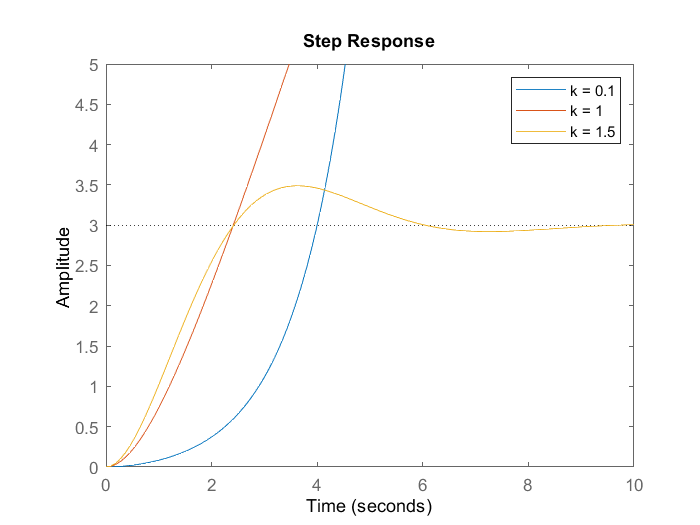

s=tf('s');
k=[0.1 1 1.5];
legend_names=string([]);
for i=1:3
G0=k(i)/(s-1)/(0.5*s+1);
step(feedback(G0,1));
legend_names(end+1) = "k = "+k(i);
hold on;
end
hold off;
ylim([0,5]);
xlim([0,10]);
legend(legend_names);

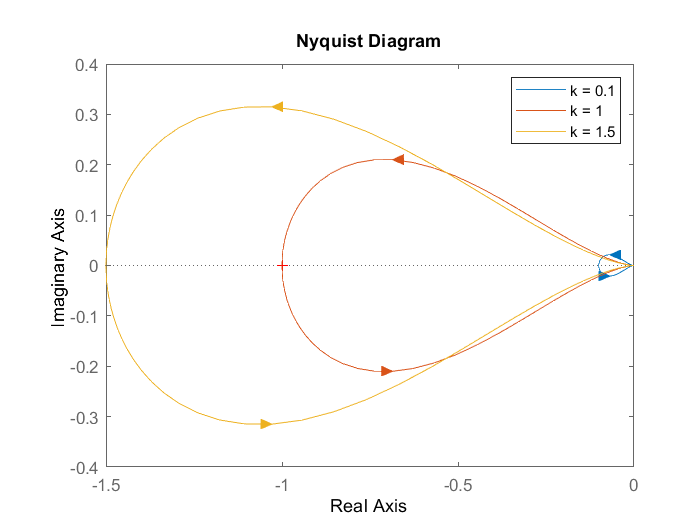


legend_names=string([]);
for i=1:3
G0=k(i)/(s-1)/(0.5*s+1);
P=nyquistplot(G0);
setoptions(P,'ShowFullContour','on')
legend_names(end+1) = "k = "+k(i);
hold on;
end
hold off;
legend(legend_names);

26

s=tf('s');
G0=4/(s-1)/(1/5*s+1)/(1/3*s+1);
GZ=feedback(G0,1)

GZ =
 
                     4
  ---------------------------------------
  0.06667 s^3 + 0.4667 s^2 + 0.4667 s + 3
 
Continuous-time transfer function.



P=pole(GZ)

P =   -6.9273 + 0.0000i
  -0.0364 + 2.5485i
  -0.0364 - 2.5485i


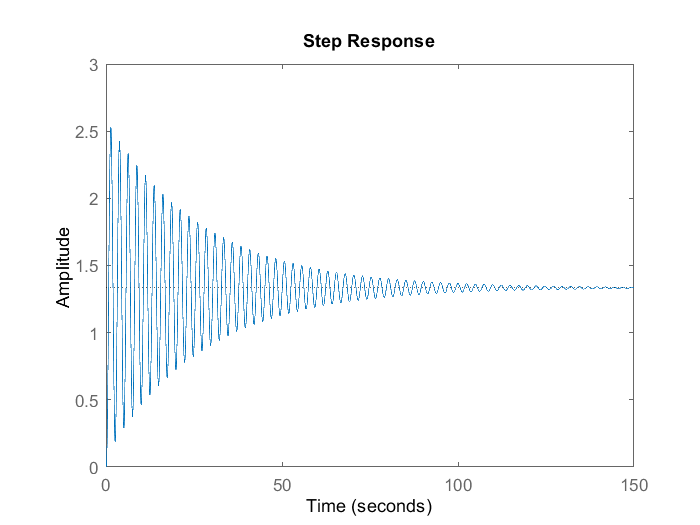

step(feedback(G0,1));

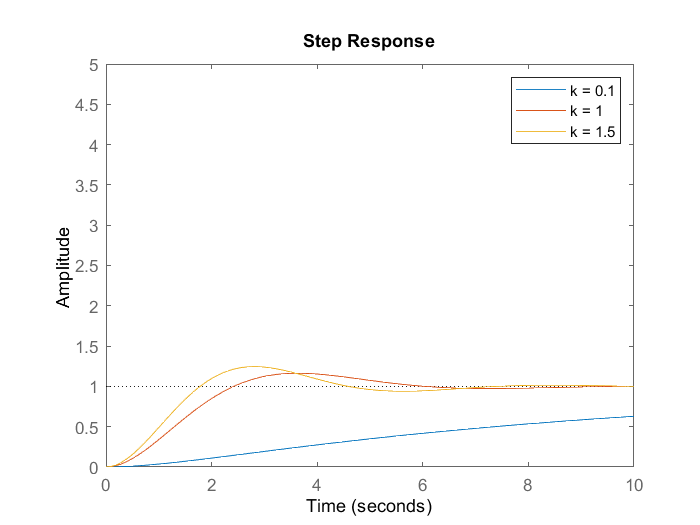

s=tf('s');
k=[0.1 1 1.5];
T=1;
legend_names=string([]);
for i=1:3
G0=k(i)/(s*(T*s+1));
step(feedback(G0,1));
legend_names(end+1) = "k = "+k(i);
hold on;
end
hold off;
ylim([0,5]);
xlim([0,10]);
legend(legend_names);

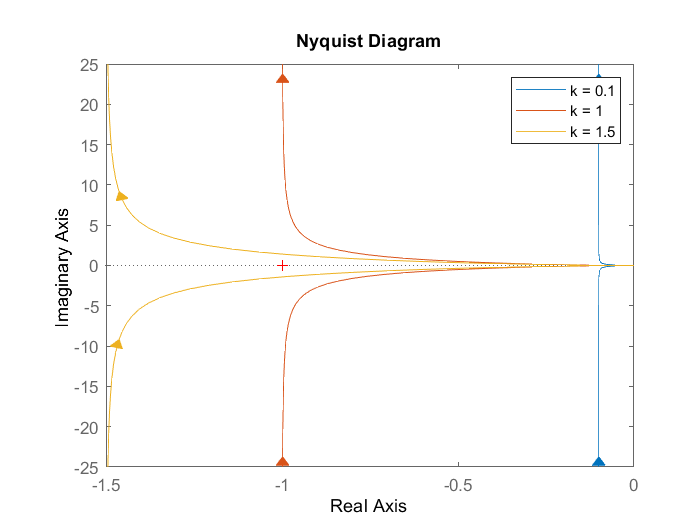


legend_names=string([]);
for i=1:3
G0=k(i)/(s*(T*s+1));
P=nyquistplot(G0);
setoptions(P,'ShowFullContour','on')
legend_names(end+1) = "k = "+k(i);
hold on;
end
hold off;
legend(legend_names);

30

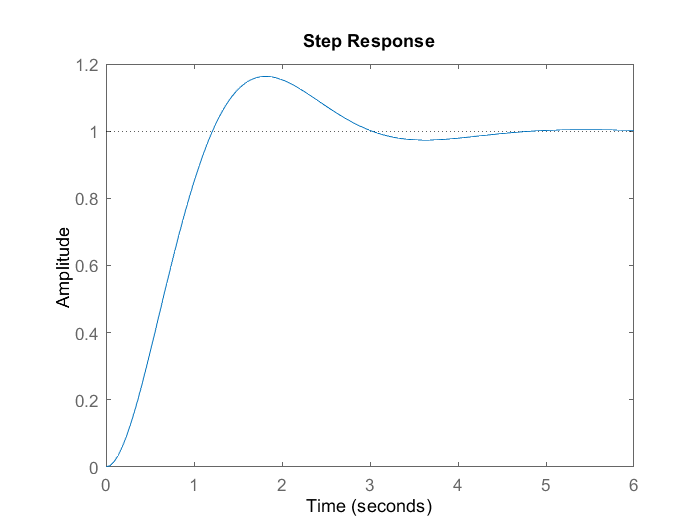

s=tf('s');
G2=4/(s^2+2*s+4);
step(G2)

P=pole(G2)

P =   -1.0000 + 1.7321i
  -1.0000 - 1.7321i


syms s
y=ilaplace(1/s*4/(s^2+2*s+4))

$$y = 1-{\mathrm{e}}^{-t}\,\left(\cos\left(\sqrt{3}\,t\right)+\frac{\sqrt{3}\,\sin\left(\sqrt{3}\,t\right)}{3}\right)$$

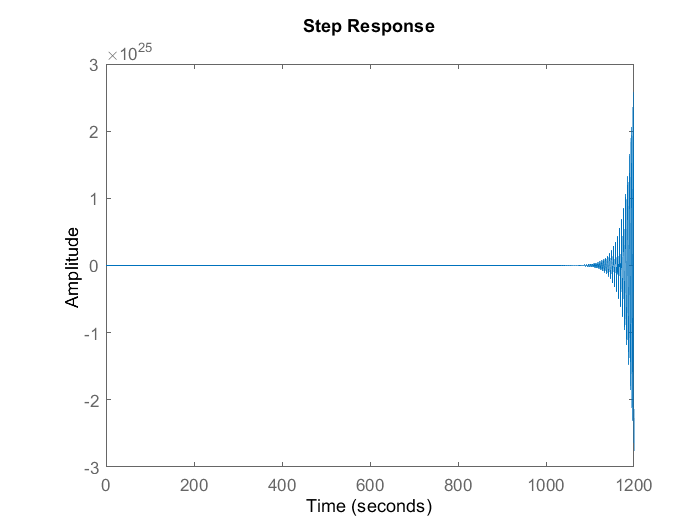

s=tf('s');
G3=0.5/(s^2-0.1*s+2);
step(G3)

P=pole(G3)

P =    0.0500 + 1.4133i
   0.0500 - 1.4133i


syms s
y=ilaplace(1/s*0.5/(s^2-0.1*s+2))

$$y = \frac{1}{4}-\frac{{\mathrm{e}}^{t/20}\,\left(\cos\left(\frac{\sqrt{799}\,t}{20}\right)-\frac{\sqrt{799}\,\sin\left(\frac{\sqrt{799}\,t}{20}\right)}{799}\right)}{4}$$

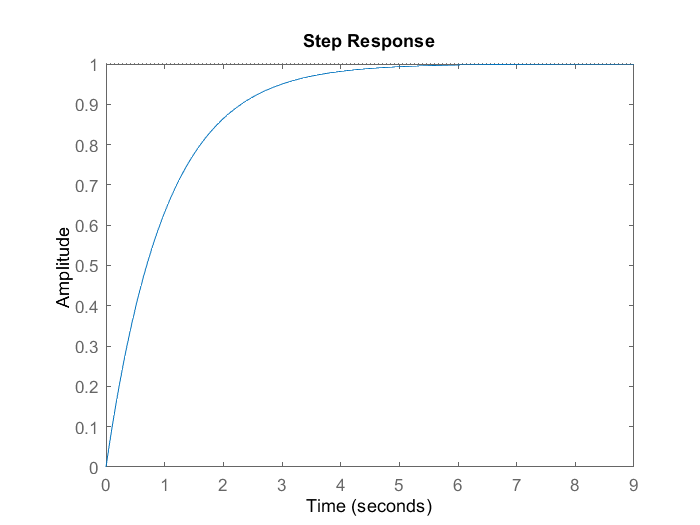

s=tf('s');
G5=1/(s+1);
step(G5)

P=pole(G5)

P = -1

syms s
y=ilaplace(1/s*1/(s+1))

$$y = 1-{\mathrm{e}}^{-t}$$

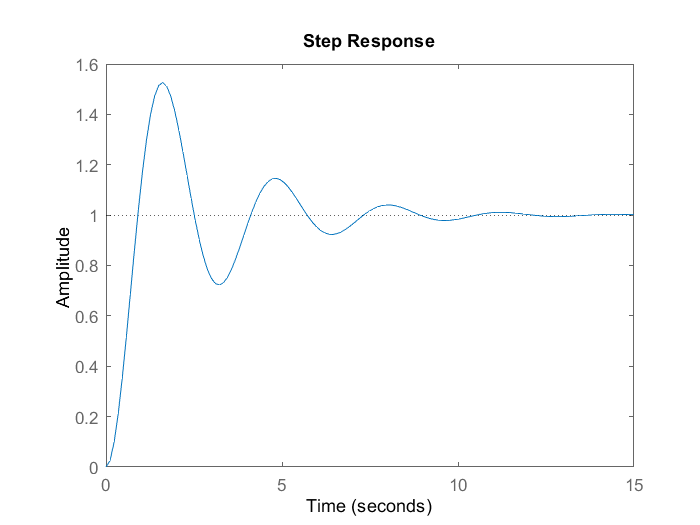

s=tf('s');
G6=4/(s^2+0.8*s+4);
step(G6)

P=pole(G6)

P =   -0.4000 + 1.9596i
  -0.4000 - 1.9596i


syms s
y=ilaplace(1/s*4/(s^2+0.8*s+4))

$$y = 1-{\mathrm{e}}^{-\frac{2\,t}{5}}\,\left(\cos\left(\frac{4\,\sqrt{6}\,t}{5}\right)+\frac{\sqrt{6}\,\sin\left(\frac{4\,\sqrt{6}\,t}{5}\right)}{12}\right)$$

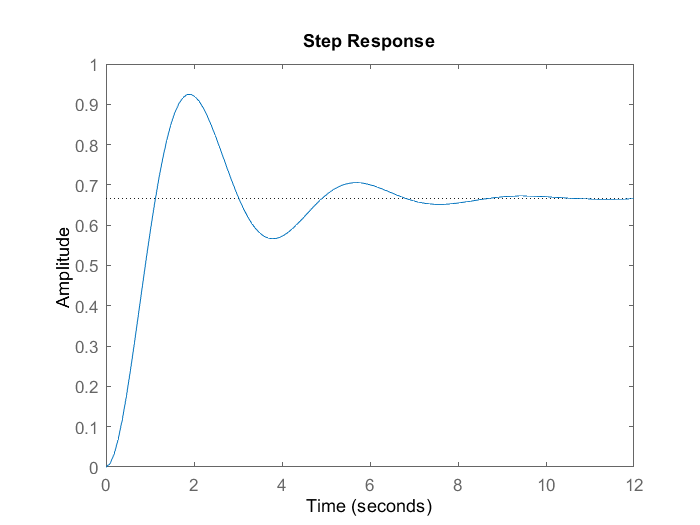

s=tf('s');
G7=2/(s^2+s+3);
step(G7)

P=pole(G7)

P =   -0.5000 + 1.6583i
  -0.5000 - 1.6583i


syms s
y=ilaplace(1/s*2/(s^2+s+3))

$$y = \frac{2}{3}-\frac{2\,{\mathrm{e}}^{-\frac{t}{2}}\,\left(\cos\left(\frac{\sqrt{11}\,t}{2}\right)+\frac{\sqrt{11}\,\sin\left(\frac{\sqrt{11}\,t}{2}\right)}{11}\right)}{3}$$

30 - Test

G=zpk([],[-1+2i, -1-2i],5)

G =
 
        5
  --------------
  (s^2 + 2s + 5)
 
Continuous-time zero/pole/gain model.



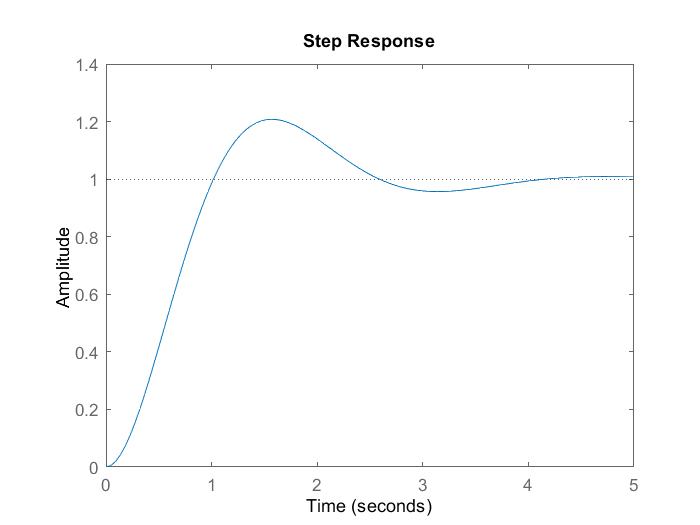

step(G)

G=zpk([],[-1+4i, -1-4i],17)

G =
 
        17
  ---------------
  (s^2 + 2s + 17)
 
Continuous-time zero/pole/gain model.



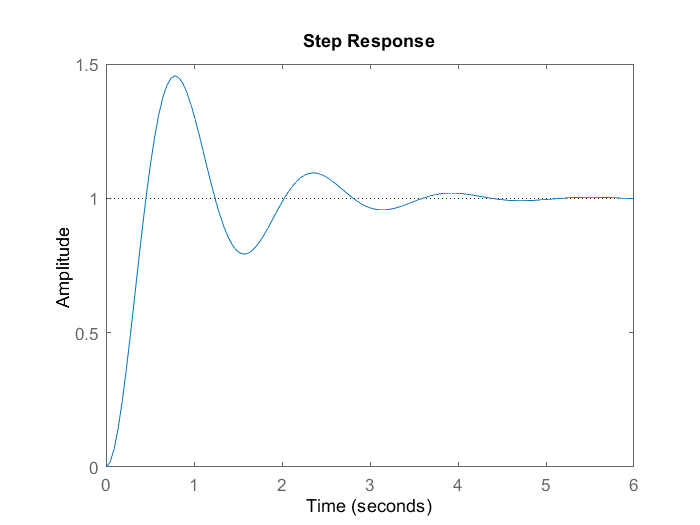

step(G)

G=zpk([],[-0.5+2i, -0.5-2i],4.25)

G =
 
        4.25
  ----------------
  (s^2 + s + 4.25)
 
Continuous-time zero/pole/gain model.



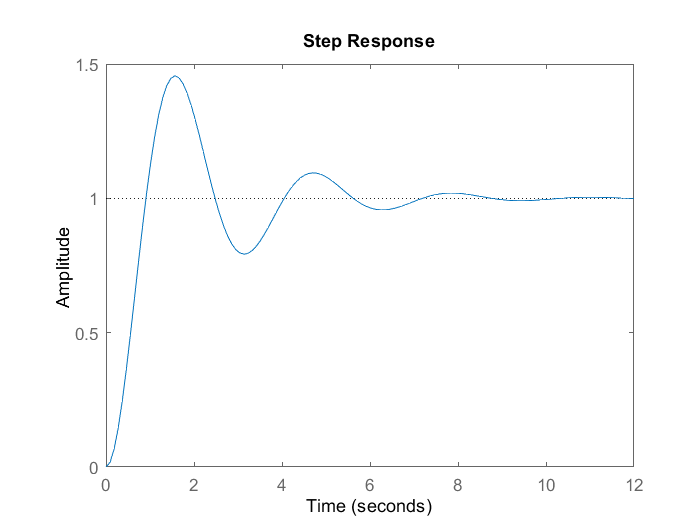

step(G)

32

syms s;
F=1/s^5/(s+1);
f = ilaplace(F)

$$f = \frac{t^{2}}{2}-{\mathrm{e}}^{-t}-t-\frac{t^{3}}{6}+\frac{t^{4}}{24}+1$$

f = diff(f,4)

$$f = 1-{\mathrm{e}}^{-t}$$


%Faster:
syms s;
F=1/s/(s+1);
f = ilaplace(F)

$$f = 1-{\mathrm{e}}^{-t}$$

33

syms s;
L=s+1;
M=2*s+1;
F=L/M

$$F = \frac{s+1}{2\,s+1}$$

f=ilaplace(F)

$$f = \frac{{\mathrm{e}}^{-\frac{t}{2}}}{4}+\frac{\delta (t)}{2}$$

34

syms s;
L=s^3-3*s^2+3

$$L = s^{3}-3\,s^{2}+3$$

M=s^2*(3*s-1)

$$M = s^{2}\,\left(3\,s-1\right)$$

F=L/M;
f=ilaplace(F)

$$f = \frac{73\,{\mathrm{e}}^{t/3}}{9}-3\,t+\frac{\delta (t)}{3}-9$$

35

syms s;
L=s^2+2*s+3

$$L = s^{2}+2\,s+3$$

M=s^2+1

$$M = s^{2}+1$$

F=L/M;
f=ilaplace(F)

$$f = 2\,\cos\left(t\right)+\delta (t)+2\,\sin\left(t\right)$$

36

syms s;
L=s^2+5*s+9;
M=s^2+4*s+7;
F=L/M;
f=ilaplace(F)

$$f = \delta (t)+{\mathrm{e}}^{-2\,t}\,\cos\left(\sqrt{3}\,t\right)$$

37

syms s;
L=s^3+3*s^2+4*s+1;
M=(s+1)^3;
F=L/M;
f=ilaplace(F)

$$f = \delta (t)+t\,{\mathrm{e}}^{-t}-\frac{t^{2}\,{\mathrm{e}}^{-t}}{2}$$

38

syms s;
L=s^3-3*s^2+3;
M=s^2*(s-3);
F=L/M;
f=ilaplace(F)

$$f = \frac{{\mathrm{e}}^{3\,t}}{3}-t+\delta (t)-\frac{1}{3}$$

39

syms s;
L=1;
M=s^2*(s^2+2*s+5);
F=L/M;
f=ilaplace(F)

$$f = \frac{t}{5}+\frac{2\,{\mathrm{e}}^{-t}\,\left(\cos\left(2\,t\right)-\frac{3\,\sin\left(2\,t\right)}{4}\right)}{25}-\frac{2}{25}$$

41

syms s k T
G=k/(1+s*T);
g=ilaplace(G)

$$g = \frac{k\,{\mathrm{e}}^{-\frac{t}{T}}}{T}$$

y=ilaplace(G/s)

$$y = k-k\,{\mathrm{e}}^{-\frac{t}{T}}$$

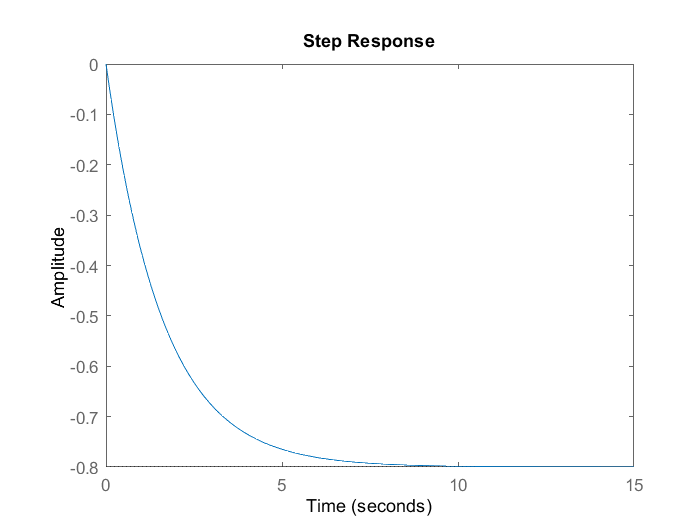


s=tf('s');
k=-4/5; T=1.6;
G0=k/(1+s*T);
step(G0)

42

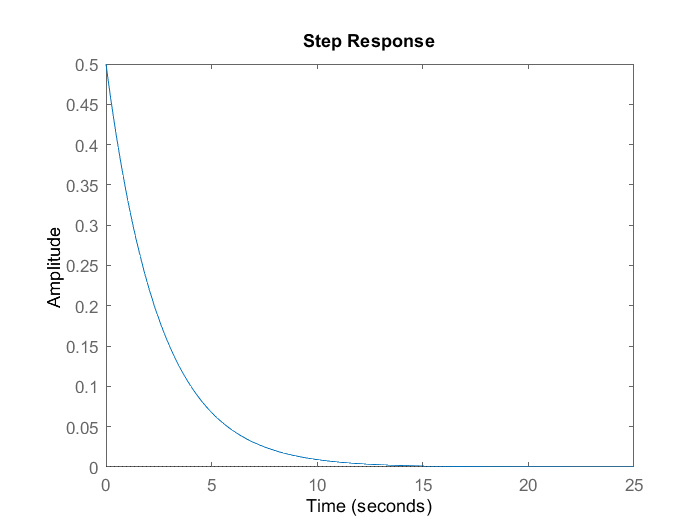

s=tf('s');
k=1.25; T=2.5;
G0=s*k/(1+s*T);
step(G0)

43

syms s k T
G=k/(s*(s*T+1));
g=ilaplace(G)

$$g = k-k\,{\mathrm{e}}^{-\frac{t}{T}}$$

y=ilaplace(G/s)

$$y = k\,t-T\,k+T\,k\,{\mathrm{e}}^{-\frac{t}{T}}$$

44

syms s
F=27/(3*s+9)^3;
f=ilaplace(F)

$$f = \frac{t^{2}\,{\mathrm{e}}^{-3\,t}}{2}$$

y=ilaplace(F/s);

57

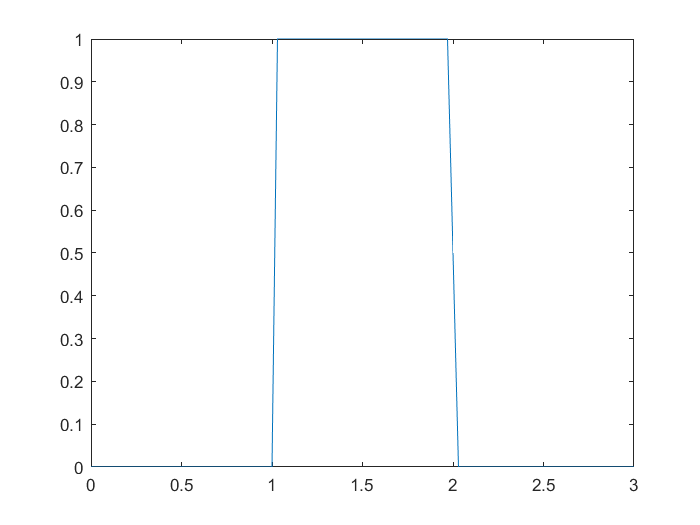

syms s;
tc=linspace(0,3);
U=exp(-s)/s-exp(-2*s)/s;
G=1/(2*s);

u =@(t) ilaplace(U,t);
y =@(t) ilaplace(U*G,t);
plot(tc,u(tc))

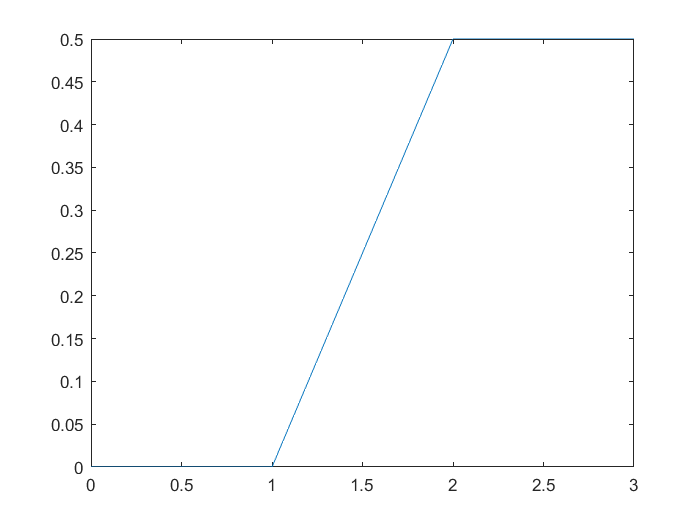

plot(tc,y(tc))

58

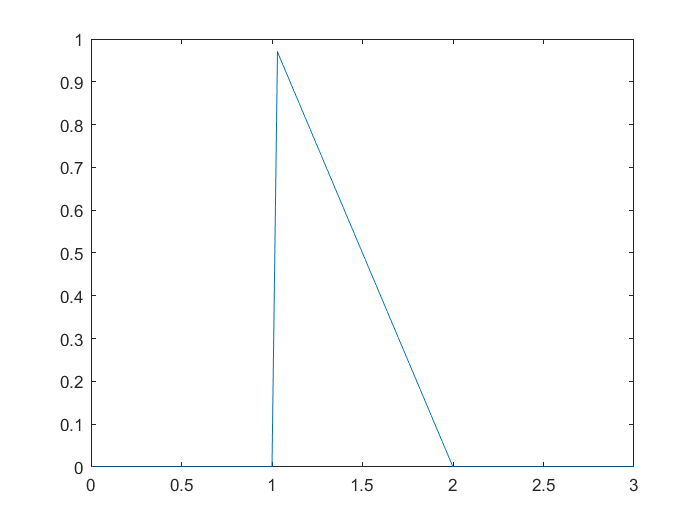

syms s;
tc=linspace(0,3);
U=exp(-s)/s-exp(-s)/s^2+exp(-2*s)/s^2;
G=2*s;

u =@(t) ilaplace(U,t);
y =@(t) ilaplace(U*G,t);
plot(tc,u(tc))

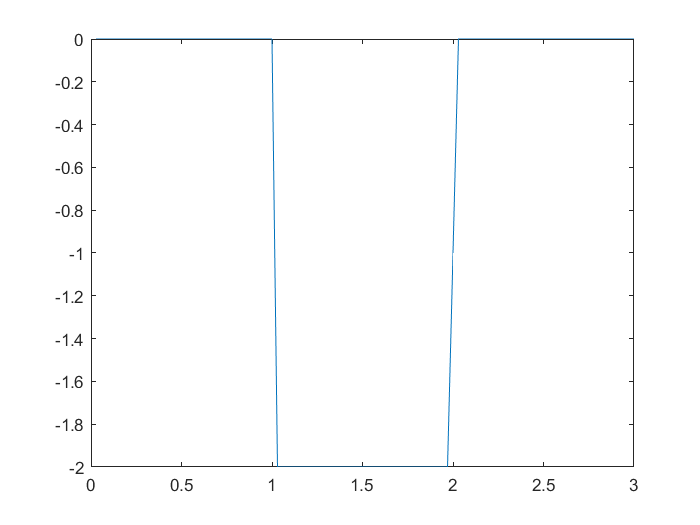

plot(tc,y(tc))

59

syms s;
tc=linspace(0,4);
U=1/2*1/s^2*exp(-s)-1/2/s^2*exp(-3*s)-1/s*exp(-3*s)

$$U = \frac{{\mathrm{e}}^{-s}}{2\,s^{2}}-\frac{{\mathrm{e}}^{-3\,s}}{s}-\frac{{\mathrm{e}}^{-3\,s}}{2\,s^{2}}$$

G=2*s;
Y=ilaplace(U*G)

$$Y = \mathrm{heaviside}\left(t-1\right)-2\,\delta (t-3)-\mathrm{heaviside}\left(t-3\right)$$

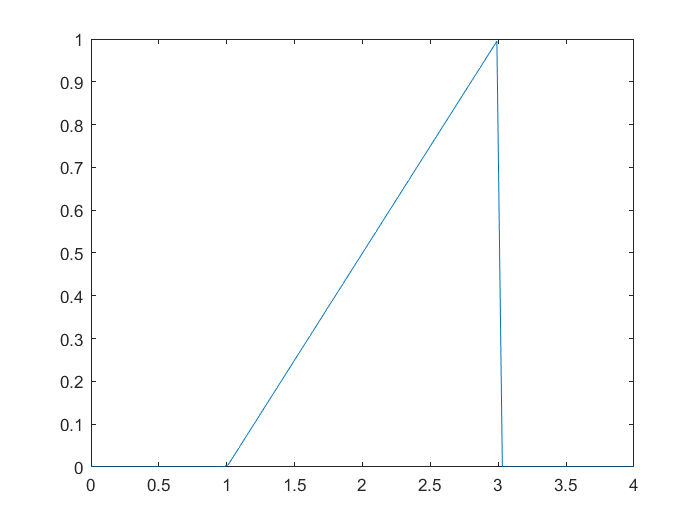

u =@(t) ilaplace(U,t);
y =@(t) ilaplace(U*G,t);
plot(tc,u(tc))

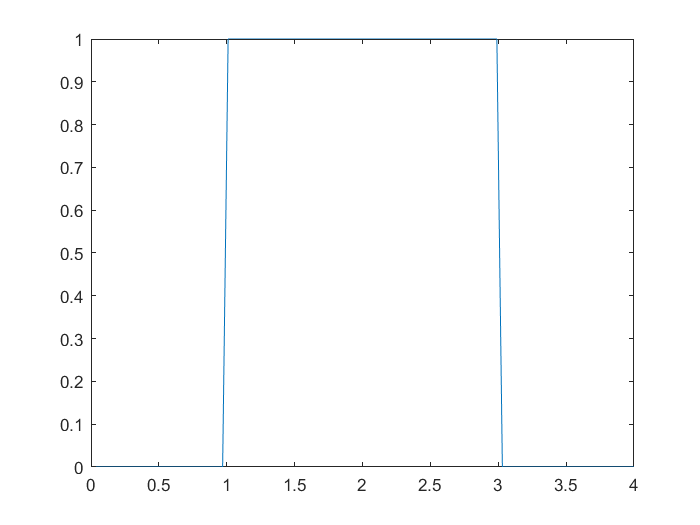

plot(tc,y(tc))

60

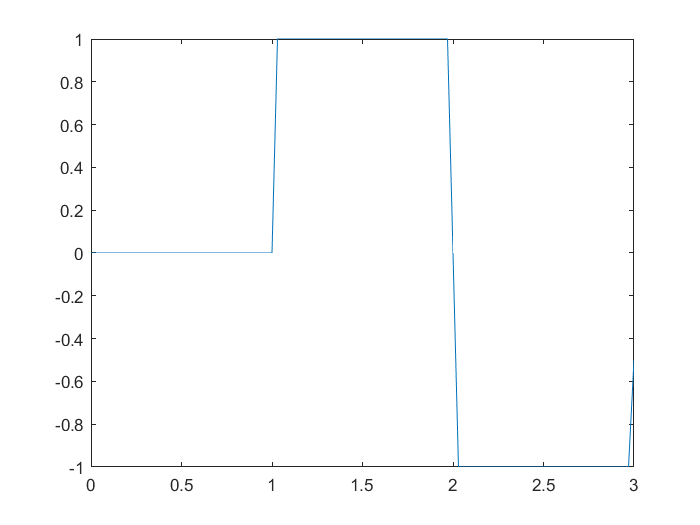

syms s;
tc=linspace(0,3);
Y=exp(-s)/s-2*exp(-2*s)/s+exp(-3*s)/s;
G=s;

y =@(t) ilaplace(Y,t);
u =@(t) ilaplace(Y/G,t);
plot(tc,y(tc))

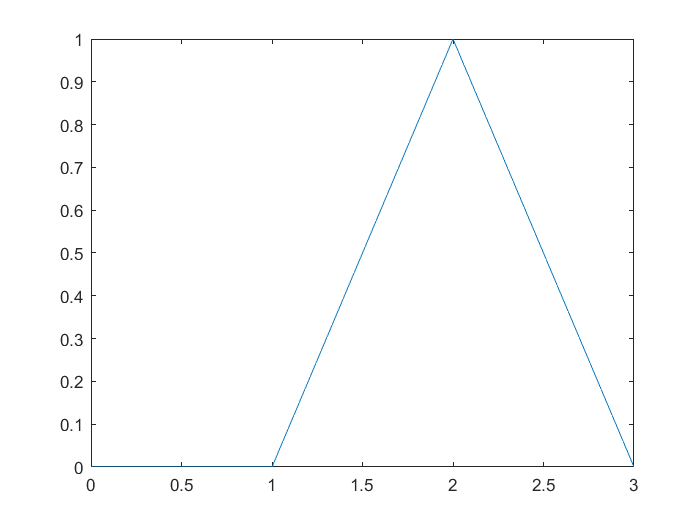

plot(tc,u(tc))

61

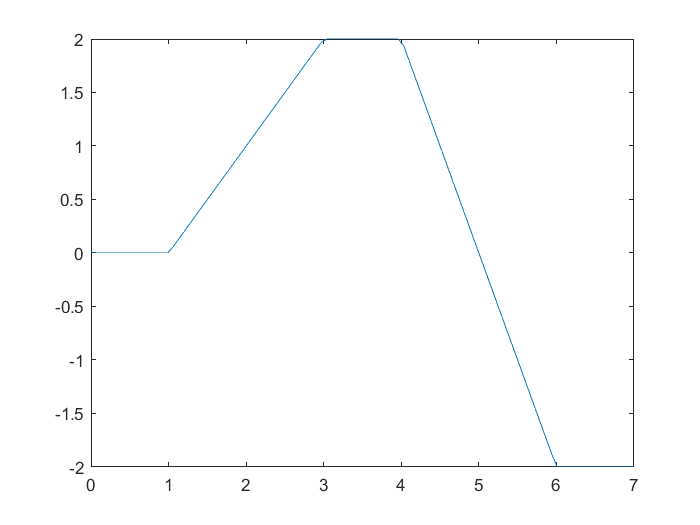

syms s;
tc=linspace(0,7);
Y=exp(-s)/s^2-exp(-3*s)/s^2-2*exp(-4*s)/s^2+2*exp(-6*s)/s^2;
G=1/s;

y =@(t) ilaplace(Y,t);
u =@(t) ilaplace(Y/G,t);
plot(tc,y(tc))

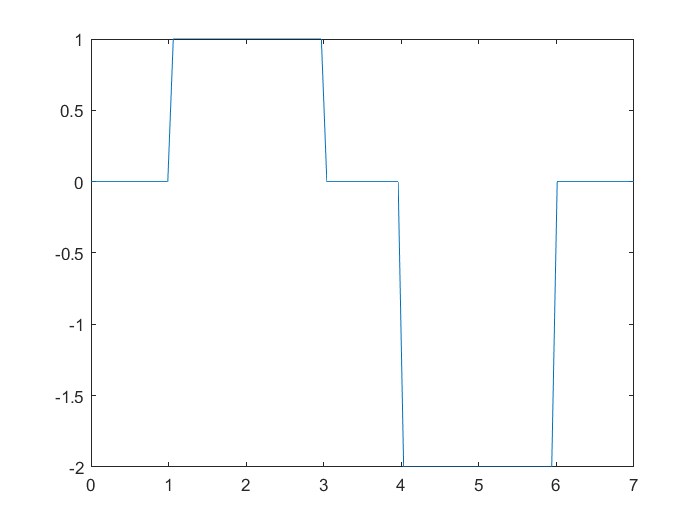

plot(tc,u(tc))

69

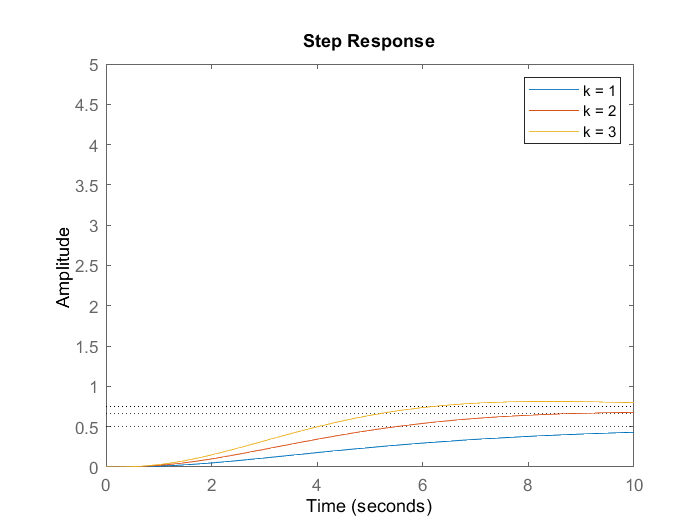

s=tf('s');
k=[1 2 3];
T=1;
legend_names=string([]);
for i=1:3
G0=k(i)/(10*s+1)/(s+1)^2;
step(feedback(G0,1));
legend_names(end+1) = "k = "+k(i);
hold on;
end
hold off;
ylim([0,5]);
xlim([0,10]);
legend(legend_names);

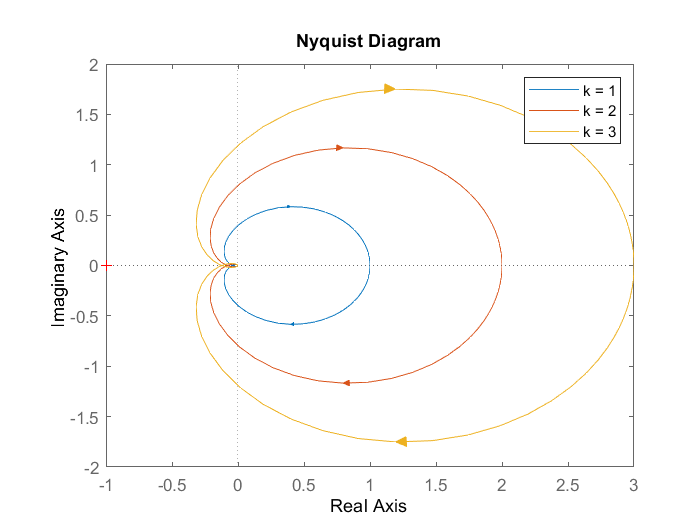


legend_names=string([]);
for i=1:3
G0=k(i)/(10*s+1)/(s+1)^2;
P=nyquistplot(G0);
setoptions(P,'ShowFullContour','on')
legend_names(end+1) = "k = "+k(i);
hold on;
end
hold off;
legend(legend_names);

70

s=tf('s');
G1=1/(s/0.1);
G2=s/0.1+1;
G3=1/(s/10+1);
G0=G1*G2*G3

G0 =
 
    s + 0.1
  -----------
  0.1 s^2 + s
 
Continuous-time transfer function.



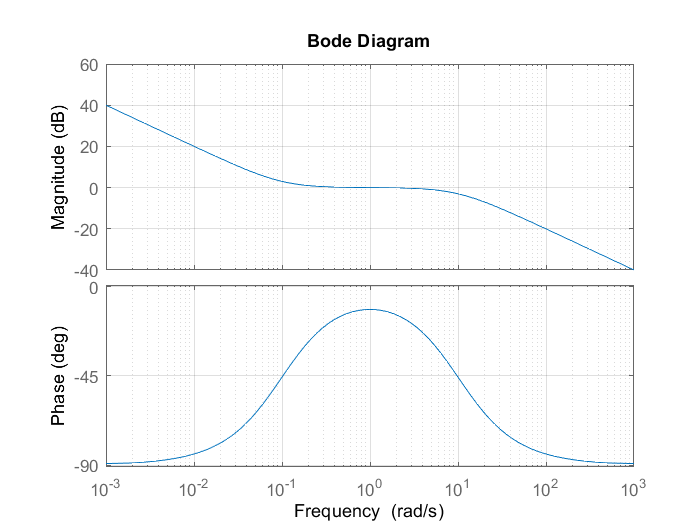

bode(G0)
grid on;

71

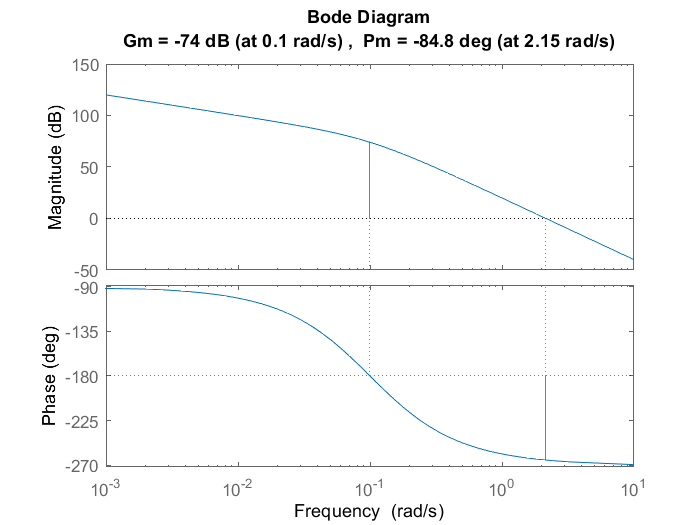

s=tf('s');
G=1000/(s*(1+0.001*s)*(1+10*s)^2);
margin(G);

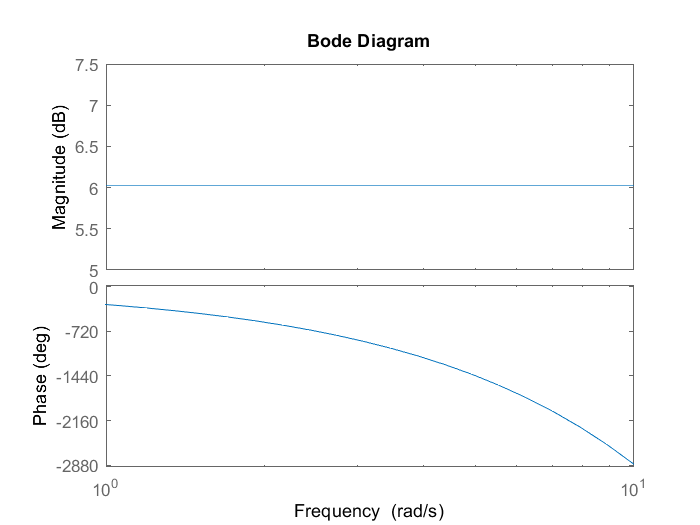

s=tf('s');
k=2; t0=5;
G=k*exp(-s*t0);
bode(G);

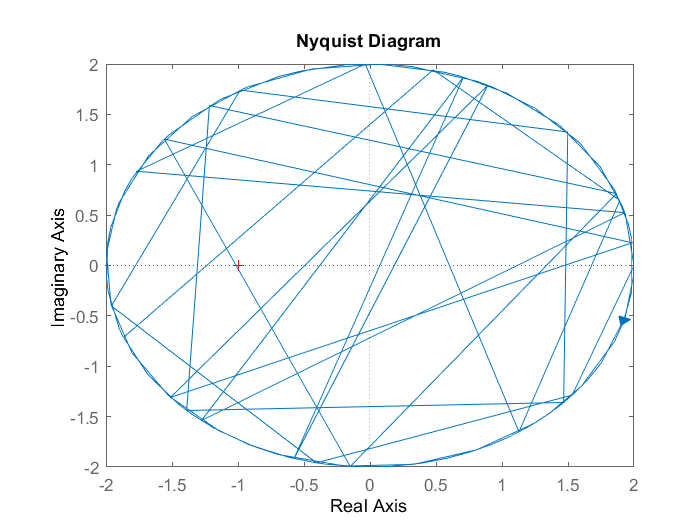

P=nyquistplot(G);
setoptions(P,'ShowFullContour','off')

74

s=tf('s');
R1=1*10^3;
R2=10*10^3;
C=100*10^(-9);
G=-(R2*C*s+1)/(R1*C*s);
bode(G)
hold on;
G=-G

G =
 
  0.001 s + 1
  -----------
   0.0001 s
 
Continuous-time transfer function.



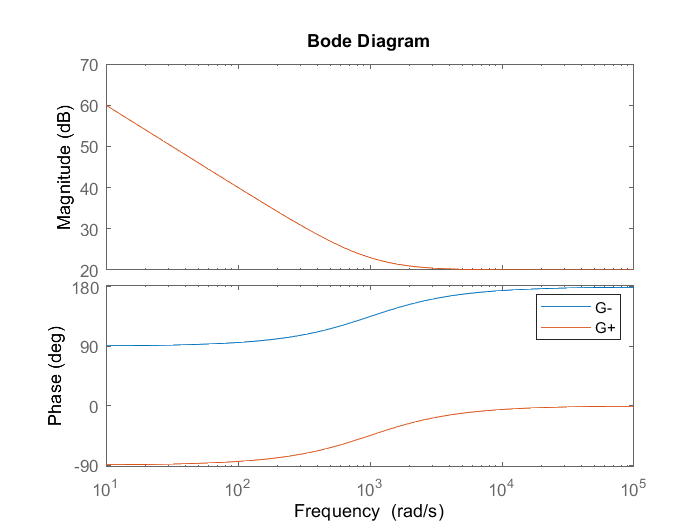

bode(G)
legend("G-","G+")
hold off;